# Home-work 3

## First Task 

*Plot two functions on the same graph for η=0.1 and η=1.1.*


$$d(\alpha) = \frac{L \cdot cos(\alpha)}{sin(\alpha)} + \frac{L \cdot \eta}{sin(\alpha)} \quad \text{(set L=1)}$$


Code from Home-Work 2.

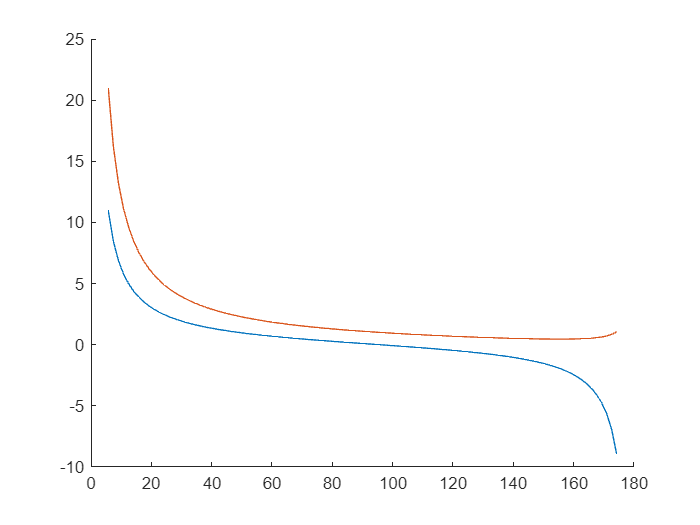

syms a eta
d = (1 * cos(a) / sin(a)) + (1 * eta / sin(a));

alpha_vals = linspace(0.1, pi-0.1);
alpha_deg = rad2deg(alpha_vals);

figure

d_sub = subs(d, a, alpha_vals);
sol = eval(subs(d_sub, eta, 0.1));

hold on
plot(alpha_deg, sol)

sol = eval(subs(d_sub, eta, 1.1));

plot(alpha_deg, sol)
hold off

## Second Task

*Write a Matlab script (step-by-step) that finds the roots of a function using the Newton method. Use your Matlab script (Newton method) and find optimal steering angle for η=0.1, 0.2, 0.3, 0.4, 0.5,  0.6, 0.7, 0.8 and 0.9*

Root is "ničla" in Slovenian, so we are searching for a value of $x$, where for some function $f$, it's value is $f(x)=0$ at $x$.

### Explaining the Newton's Method

The method works by making na initial guess for the root, e.g. $x_0$. We then have to find the tangent line of the function (first derrivative) at this point. We follow this up by calculating the intersect of the tangent line  and $x-$axis. This point becomes the new guess value - $x_1$.

This is continued until he difference between successive guesses converges (so small it doesn't matter if we find a new point).

Formula for the method:


$$x_{n+1} = x_n - \frac{f(x_n)}{f'(x_n)}$$


### Applying the Newton's Method

I will define a function `find_root`, that will apply the Newtons method. It will take two parameters, `eta` and `tol`.

- `eta` is defined as the ratio between the rivers velocity and the boat's velocity. Low eta $\Rightarrow$ smaller optimal angle.

- `tol` is the tolerance for convergence (base case for the iterator). Smaller tolerance $\Rightarrow$ more iterations.

#### Note about the Boat Problem

In our problem, we are not looking for roots specifically, but are looking for the function's minimum. The minimum occurs where it's first derrivative is 0 (meaning the slope of the tangent line is 0) or $f'(x) = 0$, which is analog to the root if $f$ at $f(x) = 0$.

We can modify the Newton's method to find the minimum of the function by finding the root of it's first derrivative. 

The second derrivative will serve as a guiding point towards a better value $x_0$.

Modified formula is then:


$$x_{n+1} = x_n - \frac{f'(x_n)}{f''(x_n)}$$


The initial guess will be set to $2\pi$.

Initialize the derrivatives and define the function

function optimal_alpha = newtons_method(d, eta, tol)

eta_values =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000


    x0 = 2*pi;
    x1 = x0;
    df = diff(d, a);

    % run until the difference is above the tolerance
    while true
        x0 = x1;

1


Unrecognized function or variable 'a'.

Error in main>newtons_method (line 21)
    df = diff(d, a);

        df_sub  = subs(df,  {a, eta}, {x0, eta});%eval?
        ddf_sub = subs(ddf, {a, eta}, {x0, eta});
        x1 = x0 - df_sub / ddf_sub;

        if abs(x0 - x1) < tol
            break;
        end
    end

    optimal_alpha = x1;
end

Calculate optimal angles for each eta value using the modified Newthons method defined with the `newtons_method`.

eta_values = 0.1 : 0.1 : 0.9
tolerance = 0.5;

for i = 1:length(eta_values)
    disp(num2str(i))
    optimal_angle = newtons_method(@(a,eta)(1 * cos(a) / sin(a)) + (1 * eta / sin(a)), eta_values(i), tolerance);
    fprintf("optimal angle: %d\n", optimal_angle);
end